% 准备区
clear;
clc;

load('data\filtering_data_no_downsampling.mat');
load('data\base_parameters_identified_20250417.mat');

g = 9.80665;
[n_sample, ~] = size(q_filt);
T = t_filt;

for k = 1 : 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);

    start_row = 1 + (k - 1) * 7;
    end_row = k * 7;

    ww(start_row : end_row, :) = compute_regression_matrix(q, qd, qdd, 1);
end
T_idy = ww * P;
T_idy = reshape(T_idy, 7, []);
T_idy = T_idy';

## VISUALIZATION

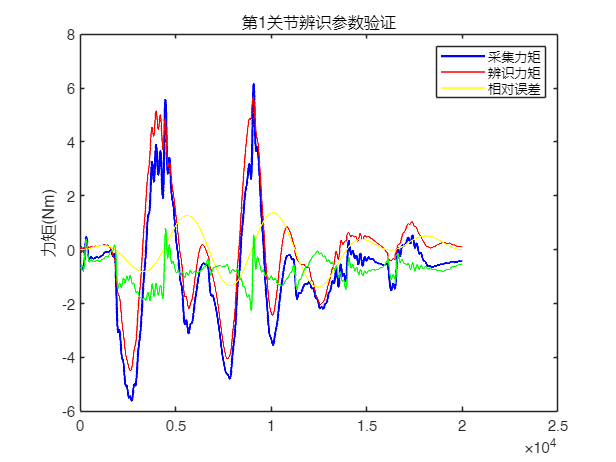

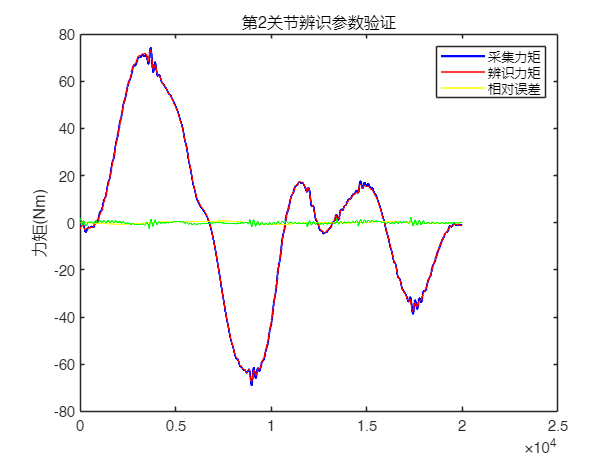

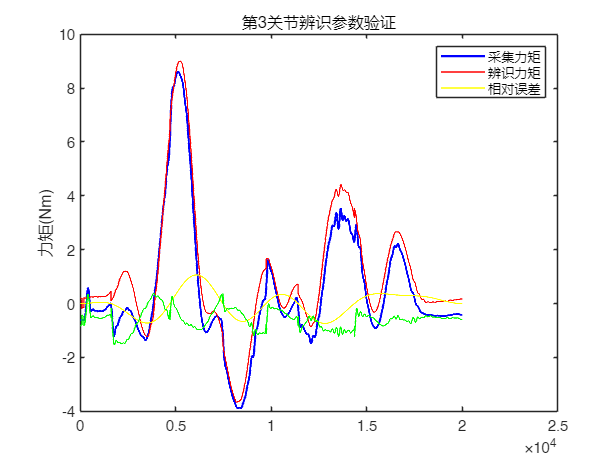

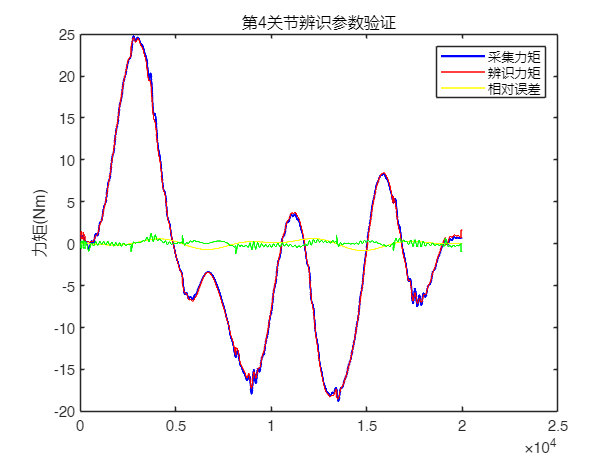

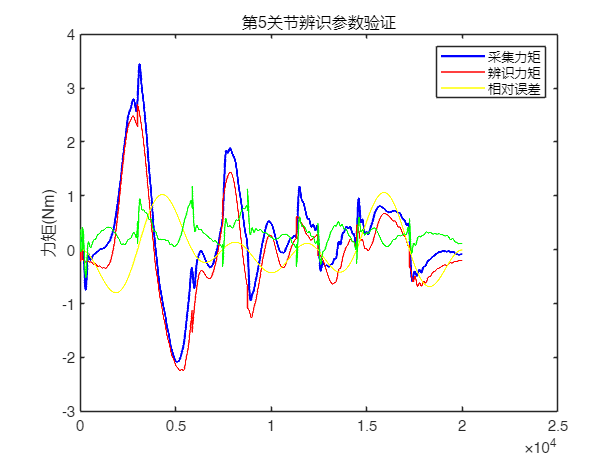

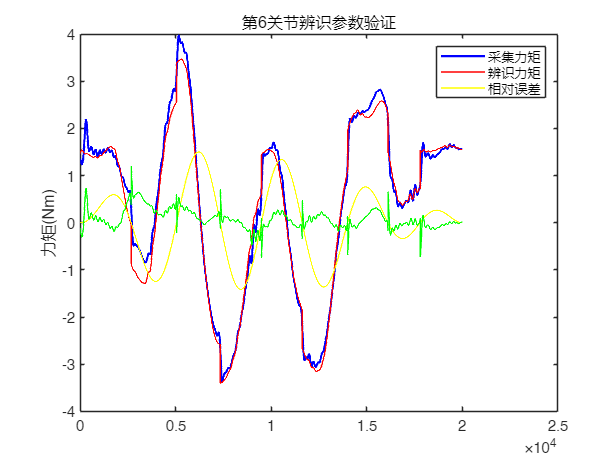

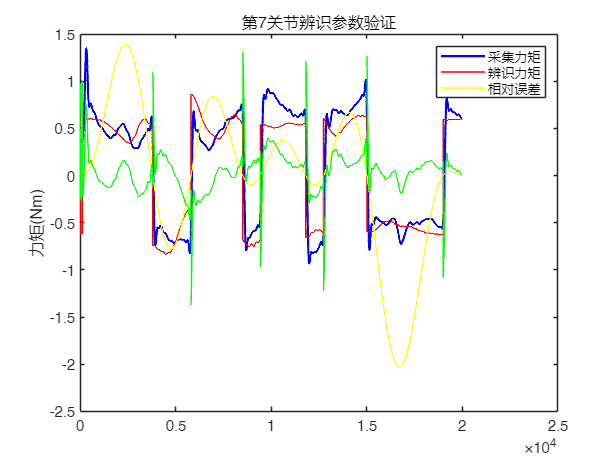

for ii = 1:7
    figure;
    plot(T(:, ii), 'b', 'LineWidth', 1.5); hold on;
    plot(T_idy(:, ii), 'r', 'LineWidth', 1.0);
    plot(qd_filt(:, ii), 'y', LineWidth=1.0);
    plot(T(:, ii) - T_idy(:, ii), 'g', 'LineWidth', 1.0); hold off;
    ylabel('力矩(Nm)');
    legend('采集力矩', '辨识力矩', '相对误差')
    title(['第', num2str(ii), '关节辨识参数验证'])
end

% for jj = 1:7
%     figure;
%     plot(t, T(:, jj) - T_idy(:, jj), 'g', 'LineWidth', 1.0);
%     title(['第', num2str(jj), '关节辨识参数误差']);
%     ylabel('力矩(Nm)')
%     set(gcf, 'Position', [-1650 500 4200 800]);
%     ax = gca;
%     exportgraphics(ax, ['.\figs\diff\diff', num2str(jj), '.png'], "Resolution", 600);
% end

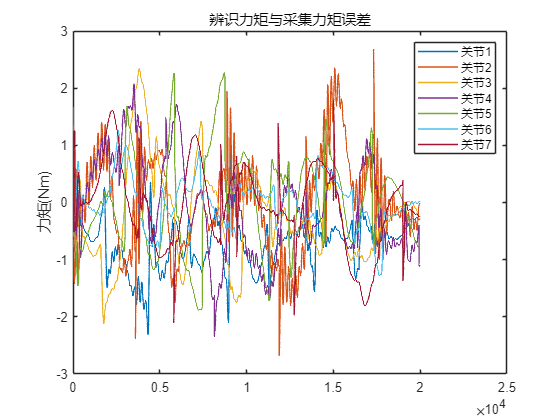

error = zeros(7, 1);
figure;
for kk = 1:7
    plot(T(:, kk) - T_idy(:, kk), 'LineWidth', 1.0); hold on;
    error(kk) = sum((T(:, kk) - T_idy(:, kk)).^2);
end

ylabel('力矩(Nm)');
legend('关节1', '关节2', '关节3', '关节4', '关节5', '关节6', '关节7')
title('辨识力矩与采集力矩误差')